## Experiment No: 01

**Name of the Experiment:** MATLAB basic for transfer function and Laplace transform.

**Objectives:** To handle polynomials in MATLAB and Laplace transform using MATLAB.

### i) Handling Polynomials in MATLAB

The polynomials have a very significant role to play in engineering systems analysis. The polynomial functions are stored in polyfun directory in MATLAB.

Some of the important commands and functions are explored below:

#### Row Vector y = [ ... ]

Polynomial representation in MATLAB. A polynomial is represented by a row vector. Only the coefficients of the polynomials are entered through the keyboard.

To represent,


$$P\left(S\right)=S^4 +{3S}^3 -{15S}^2 -2S+9$$


MATLAB Command:

To represent,


$$P\left(S\right)=S^3 +1$$


MATLAB Command:

MATLAB can interpret a vector of length (n + 1) as an n'th order polynomial. Thus, if there are any missing terms, zeros must be entered in the appropriate places in the vector.

Now try is yourself for the polynomial : $P\left(S\right)={6S}^4 -{2S}^3 +{12S}^2 +4$

global row_vec

% Write your code here:
row_vec = [6 -2 12 0 4]

row_vec =      6    -2    12     0     4


%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(1))

Correct


#### polyval()

Evaluates a given polynomial at a given point.

To evaluate $Y\left(S\right)={2S}^2 +3S+4$ at $S=1$

MATLAB Command:

Now evaluate the polynomial *row_vec *at *S = 2*

global polyval_res

% Write your code here:
polyval_res = polyval(row_vec, 2)

polyval_res = 132

%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(2))

Correct


#### roots()

Finds the roots of a polynomial.

To find the roots of $Y\left(S\right)=S^2 +3S+2$

MATLAB Command:

Now find the roots of the polynomial: $Y\left(S\right)=S^2 -7S+10$

global roots_of_poly

% Write your code here:
y = [1 -7 10]

y =      1    -7    10


roots_of_poly = roots(y)

roots_of_poly =      5
     2


%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(3))

Incorrect


#### conv()

Multiplies two polynomials.

To find the product of two polynomials $\textrm{Y1}\left(S\right)=S^2 +4S+8$ and $\textrm{Y2}\left(S\right)=S+2$

MATLAB Command:

Now find the products of: $\textrm{Y1}\left(S\right)=S+3$, $\textrm{Y2}\left(S\right)=S+2$ and $\textrm{Y1}\left(S\right)=S+6$. Use two convolution operations.

global conv_res

% Write your code here:
y1 = [1 3]

y1 =      1     3


y2 = [1 2]

y2 =      1     2


y3 = [1 6]

y3 =      1     6


conv_res = conv(conv(y1, y2), y3)

conv_res =      1    11    36    36


%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(4))

Correct


#### deconv()

Division of two polynomials.

Divide the polynomial *Z* by *Y* if, $Z\left(S\right)=S^3 +{6S}^2 +16S+16$ and $Y\left(S\right)=S^2 +4S+8$

MATLAB Command:

Note that, x is the quotient and r is the remainder.

Now divide $Z\left(S\right)=S^3 +{11S}^2 +36S+36$ by $Y\left(S\right)=S+6$.

global deconv_res

% Write your code here:
z = [1 11 36 36]

z =      1    11    36    36


y = [1 6]

y =      1     6



deconv_res = deconv(z, y)

deconv_res =      1     5     6


%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(5))

Correct


#### poly()

Can be used to form a polynomial equation from it's roots.

Determine the quadratic equation whose roots are $2+3i$ and $2-3i$.

MATLAB Command:

Now find the quadratic equation whose roots are $5+2i$ and $5-2i$.

global poly_res

% Write your code here:
r = [5 + 2i, 5 - 2i]

r =    5.0000 + 2.0000i   5.0000 - 2.0000i



poly_res = poly(r)

poly_res =      1   -10    29


%Grader Function [DO NOT EDIT]
disp(autograder_lab_1(6))

Correct


#### printsys()

Can be used to print a rational fraction from its numerator and denominator.

Print the fraction $G\left(S\right)=\frac{S+3}{S^2 +2S+3}$

MATLAB Command:

Now print the fraction $G\left(S\right)=\frac{16}{S^2 +8S+16}$

% Write your code here:
num = [16]

num = 16

den = [1 8 16]

den =      1     8    16



%Print the fraction using printsys()
printsys(num, den, 's')

 
num/den = 
 
         16
   --------------
   s^2 + 8 s + 16


Expected outcome:

#### step()

The step function can be used to check the step response of any given system.

Find the step response of $G\left(S\right)=\frac{16}{S^2 +8S+16}$

MATLAB Command:

Now check the step reponse of $G\left(S\right)=\frac{16}{S^2 +\textrm{aS}+16}$ for different values of *a*.

a =10

a = 10

% Write your code here:
num = [16]

num = 16

den = [1 a 16]

den =      1    10    16



%Find the step reponse
printsys(num, den, 's')

 
num/den = 
 
          16
   ---------------
   s^2 + 10 s + 16



roots(den)

ans =     -8
    -2


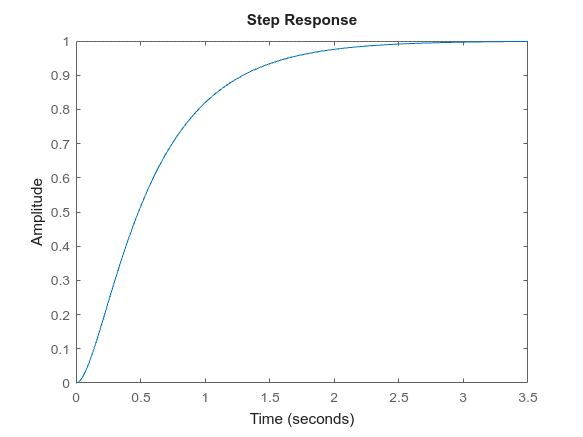

step(num, den)

Observe the change in the step response with different values of *a*.

#### residue()

It is used to expand a rational fraction to partial fractions. Or, to get back rational fraction from partial fraction.

Resolve the polynomial $G\left(S\right)=\frac{S^3 +9S+1}{S^3 +S^2 +2S+2}$ into partial fractions.

MATLAB Command:

The reverse can be done by:

Now resolve the polynomial $G\left(S\right)=\frac{S+4}{{2S}^2 +5S+3}$ into partial fractions. Also revert the partial fraction into rational fraction.

% Write your code here:
num = [1 4]

num =      1     4


den = [2 5 3]

den =      2     5     3



%Convert the rational fraction into partial fraction.
[r, p, k] = residue(num, den)

r =    -2.5000
    3.0000


p =    -1.5000
   -1.0000



k =

     []




%Now convert the partial fraction back into rational function
[num, den] = residue(r, p, k)

num =     0.5000    2.0000


den =     1.0000    2.5000    1.5000


printsys(num, den, 's')

 
num/den = 
 
       0.5 s + 2
   -----------------
   s^2 + 2.5 s + 1.5


#### tf2zp()

This function finds the zeros, poles and gains of a transfer function.

Find zeros, poles and gains of $G\left(S\right)=\frac{{2S}^2 +8S+6}{{S^4 +{6S}^3 +12S}^2 +24S}$

MATLAB Command:

Now find the zeros, poles and gain of $G\left(S\right)=\frac{S+5}{\left(S+2\right)\left(S+3\right)}$.

% Write your code here:
num = [1 5]

num =      1     5


den = [1 5 6]

den =      1     5     6



%Find the zeros, poles and gain using tf2zp.
[z, p, k] = tf2zp(num, den)

z = -5

p =    -3.0000
   -2.0000


k = 1

#### pzmap()

This function plots the zeros amd poles of a transfer function.

Map the zeros and poles of $G\left(S\right)=\frac{{2S}^2 +8S+6}{{S^4 +{6S}^3 +12S}^2 +24S}$

MATLAB Command:

Now map the zeros and poles of $G\left(S\right)=\frac{S+5}{\left(S+2\right)\left(S+3\right)}$.

% Write your code here:
num = [1 5]

num =      1     5


den = [1 5 6]

den =      1     5     6


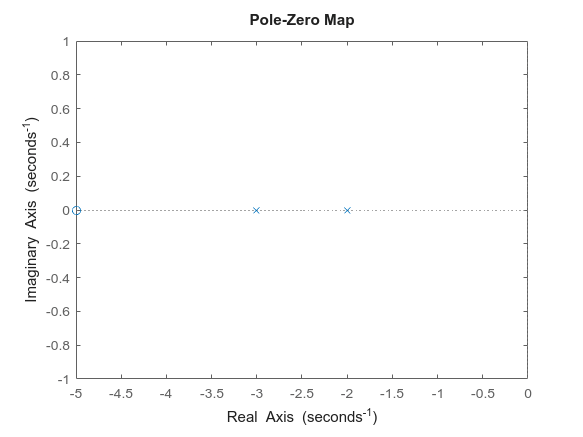


%Map the zeros and poles using pzmap.
pzmap(num, den)

#### zp2tf()

This function constructs a transfer function from zeros, poles and gain.

Find the transfer function of the system where zeros = $-3,-1$, poles = $-2,-4,-6$ and gain is $10$.

MATLAB Command:

Now find the transfer function of the system where zeros = $-2,-1$, poles = $-1,-3,-4$ and gain is $5$.

% Write your code here:
z = [-2; -1]

z =     -2
    -1


p = [-1; -3; -4]

p =     -1
    -3
    -4


k = 5

k = 5


%Find the transfer function using zp2tf().
[num, den] = zp2tf(z, p, k)

num =      0     5    15    10


den =      1     8    19    12


printsys(num, den)

 
num/den = 
 
      5 s^2 + 15 s + 10
   -----------------------
   s^3 + 8 s^2 + 19 s + 12


### ii) Laplace Transform using MATLAB

Laplce transform helps in converting differential equations describing the behaviour of dynamic systems into algebraic equations of complex variable *s*. Mathematically the Laplace transform of a function $f\left(t\right)$ is given by,


$$L\left\lbrack f\left(t\right)\right\rbrack =F\left(S\right)=\int_0^{\infty } f\left(t\right)e^{-\textrm{st}} \;d\;t$$


Laplce transformation $F\left(S\right)$ of a function $f\left(t\right)$ and the inverse Laplace transform of a function can be obtained in the following ways:

#### laplace()

This function finds the laplace transform of $f\left(t\right)$.

Find the Laplace transform of the function: $f\left(t\right)=e^{-t} \ldotp \left(1-\sin \;t\right)$

MATLAB Command:

Now find the Laplace transform of $t\;\cos \;t$. Also use ilaplace() to reverse the process.

% Write your code here:
syms t

ft = t * cos(t)

$$ft = t\,\cos\left(t\right)$$

fs = laplace(ft)

$$fs = \frac{2\,s^{2}}{{\left(s^{2}+1\right)}^{2}}-\frac{1}{s^{2}+1}$$

ft = ilaplace(fs)

$$ft = t\,\cos\left(t\right)$$